## [XGBoost Classifier](https://apmonitor.com/pds/index.php/Main/XGBoostClassifier)

XGBoost (eXtreme Gradient Boosting) is a powerful and widely-used gradient boosting algorithm that is used to solve many different types of machine learning problems. It is an implementation of gradient boosting that is specifically designed to be efficient and scalable, making it a popular choice for working with large datasets.

Mathematically, XGBoost is an ensemble learning method that combines the predictions of multiple weak models to produce a strong prediction. The weak models in XGBoost are decision trees, which are trained using gradient boosting. This means that at each iteration, the algorithm fits a decision tree to the residuals of the previous iteration.

The decision trees in XGBoost are trained using the following objective function:


$$\min_{\theta } \left(\sum_{i=1}^n l\left(y_i ,{\overset{\wedge }{y} }_i \right)+\sum_{k=1}^K \Omega \left(f_k \right)\right)$$


where *l* is the loss function, $y_i$ is the true label of the *i*th training example, ${\overset{\wedge }{y} }_i$ is the predicted label of the *i*th training example, $f_k$ is the *k*th decision tree, and Ω is a regularization term that penalizes the complexity of the trees. This objective function is optimized using gradient descent.

Once the decision trees have been trained, XGBoost makes predictions by combining the predictions of all the trees using a weighted average. The weights for each tree are learned during training using the same objective function. This allows the algorithm to automatically learn which trees are more important and should be given more weight in the final prediction.

XGBoost is a multi-platform gradient boosting package that implements a gradient boosting framework. The algorithm is scalable for parallel computing. XGBoost has gained attention in machine learning competitions as an algorithm of choice for classification and regression.

**Advantages:** Effective with large data sets. Tree algorithms such as XGBoost and Random Forest do not need normalized features and work well if the data is nonlinear, non-monotonic, or with segregated clusters.

**Disadvantages:** Tree algorithms such as XGBoost and Random Forest can over-fit the data, especially if the trees are too deep with noisy data.

**Optical Character Recognition with XGBoost**

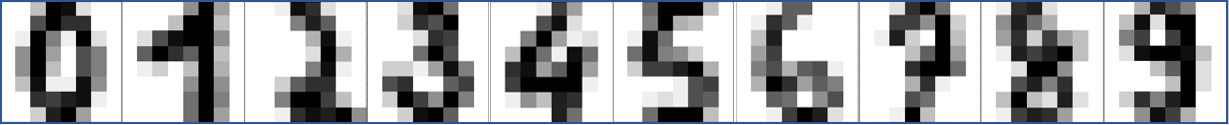

In the context of optical character recognition (OCR), XGBoost could be used to train a model to recognize characters in images of text.

For more information on XGBoost in MATLAB, view the following links.

[What functionality does MATLAB offer for Gradient Boosting that is equivalent to XGBoost? - MATLAB Answers - MATLAB Central (mathworks.com)](https://www.mathworks.com/matlabcentral/answers/457195-what-functionality-does-matlab-offer-for-gradient-boosting-that-is-equivalent-to-xgboost)

[Machine learning gradient boosting - MATLAB Answers - MATLAB Central (mathworks.com)](https://www.mathworks.com/matlabcentral/answers/1436097-machine-learning-gradient-boosting?s_tid=ans_recom_leaf)

You can also view AdaBoost to view how these functions are implemented into MATLAB.

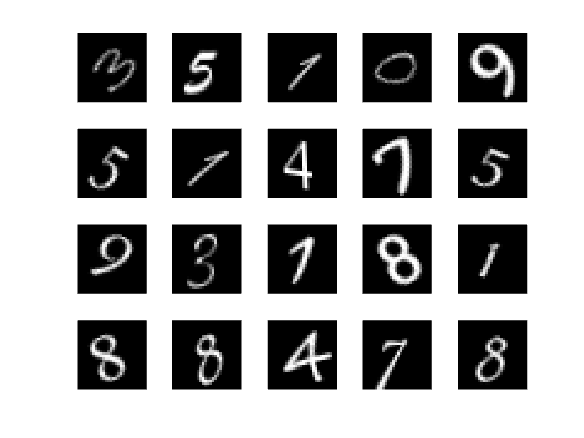

% Import dataset of numbers
digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

% Show example of dataset
figure;
perm = randperm(10000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

n_samples = length(imds.Files);

% Extract the images into a matrix
X_data = [];
for i = 1:n_samples
    X_data = [X_data; reshape(readimage(imds,i)',[1,28*28])];
end

% Save the labels of the images
Y_data = imds.Labels(1:n_samples);

% Split the data 50% training adn 50% testing
[trainInd,valInd,testInd] = dividerand(n_samples,0.5,0,0.5);

X_Train = X_data(trainInd,:);
X_Test = X_data(testInd,:);
Y_Train = Y_data(trainInd,:);
Y_Test = Y_data(testInd,:);

% Create fit
classifier = fitcensemble(array2table(im2double(X_Train)),Y_Train,'Method','AdaBoostM2');

% Evaluate the model performance on the test set
y_pred = predict(classifier,array2table(im2double(X_Test)));
accuracy = mean(y_pred == Y_Test);
fprintf("Accuracy: %.2f\n", accuracy);

Accuracy: 0.63


Below is an example that also shows a number from the test set that is evaluated with the AdaBoost classifier.

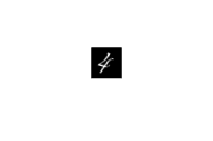

tbl = [array2table(im2double(X_Train)), array2table(Y_Train)];

% Select random nummber image
n = randi([0,n_samples],1);
figure;
imshow(imds.Files{n})

reshape(readimage(imds,n)',[1,28*28]);

% Predict number based on image
yp = predict(classifier,im2double(reshape(readimage(imds,n)',[1,28*28])));
disp(['Predicted:',yp])

     Predicted:      6 

